# Lesson 2

Written by Brenda So and Cory Nezin, modified by Guy Bar Yosef.

# Objective

After this class, you should be able to:

- Be comfortable operating on vectors and matricies in MATLAB

- Understand how to index vectors and matricies both linearily and logically

# Vector Operations

In lesson 1, we see how to make a vector with the colon operator and linspace. However, had MATLAB only allowed us to use those two operations to create vectors, MATLAB would be pretty useless. 

MATLAB is often used to perform numerical analysis, hence it would be very useful if we can input vectors into functions so as to generate another vector. Luckily, MATLAB can do that! Note that when you perform many of these operations, they are applied element-wise for vectors. 

x = 0:0.01:2*pi;    % You create a vector
y = sin(x);         % Here, you perform a transformation from one vector to another
xlen = length(x)
ylen = length(y)    % xlen and ylen is equal!
plot(x,y)

## Exercise 1 : Vector Operations

Create a vector t, where t ranges from 0 to 2 millisecond with increments T = 1e-6, and create another vector y1, where $f_{0\text{ }} =50\text{ }Hz$ and $\beta =10\text{ }M\text{Hz}\text{ }s^{-1}$ such that:


$$y_1 \left(t\right)=10cos\left(2\pi f_{0\text{ }} t+\pi \beta t^2 \right)$$


t = 0:1e-6:2e-3;
f0 = 50;
beta = 10e6;
y1 = 10*cos(2*pi*f0 + pi*beta*t.^2);

figure
plot(t,y1)

# Some Matrix Operations

Matricies are closely related to vectors and we have explored some matrix operations the previous class. This lesson, we will add to our knowledge by going over row-wise and column-wise operations.

## Row-wise / Column-wise operations

H = magic(4)     % create the magical matrix H
sum(H,1)         % column wise sum, note that this is a row vector(default)  
mean(H,1)        % mean along the columns
fliplr(H)        % flip H from left to right
flipud(H)        % flip H upside down
H(1,:) = fliplr(H(1,:)) % flip only ONE row upside down
H(1,:) = []      % delete the first column

Note that in matlab there is not ++ or += commands. Instead we can do:

a = 4;
a = a + 1;     % incrementing a by 1
v = [1 2 3 4];
v = [v 5]      % appending a value to the end of a vector. Look at note below!

**NOTE: **The appending operation above is inefficient and can (and should) be avoided by preallocating an appropriately sized vector beforehand and using indexes!

v = ones(1,5);
v(1:4) = [1 2 3 4];
disp(v(1:4))
v(5) = 5;
disp(v)

 Read along to learn more about indexing!

# Indexing in MATLAB

To inspect certain values in vectors x and y, we can use indexing. We are going to delve into linear indexing as well as logical indexing.

## Basic Indexing

x = 0:0.1:2;
x(1) % MATLAB has 1-based indexing! 
x(5)
x(2:5)
x(end)
x(end-1)
x(:)        % the elements of x as a column vector

Of course, we can perform more complicated arithmetic operations on vectors, just as we can do with scalars. What's more, there are many pre-built functions in matlab that allows us to obtain certain statistics (such as *mean* above). There are A LOT of such functions but we are only showing a few of the more commonly used ones here. Search through the documentation to find others!

## BE CAREFUL!

In other languages, indices start at 0, however, in MATLAB, **indices start at 1**. Hence in matlab, the last index would be the length of the vector itself. 

# Indexing Vectors

Another thing to note is that you can use a vector to index a vector. This could be particularly useful if you want to obtain a range of values in a single vector. 

x([1 3 5 7])    % Indexing the 1,3,5,7th element in x
x(1:2:7)        % You're basically doing the same thing as above
x([5:8 1:4])    % WRITEME IN COMMENTS! : What does this line do?
x([1:4]) = 40   % WRITEME IN COMMENTS! : What does this line do?

# Indexing Matrices with Two subscripts

Indexing with 2 subscripts is very intuitive: you specify the row first, and then the column. Note that unlike in many other programming languages, we use curly brackets instead of square brackets for indexing.

A = [16 2 3 13; 5 11 10 8; 9 7 6 12; 4 14 15 1]
A(1,4)    % Extract the element in row 1, column 4

You can also extent it into the more general case, where one or both of the row and column can be vectors

A(1:3, 1:2)    % WRITEME IN COMMENTS!: What do I do?
A(end,:)       % WRITEME IN COMMENTS!: What do I do?
A(:,3)         % WRITEME IN COMMENTS!: What do I do? 

However, indexing with 2 subscripts has its limitations. For example, suppose you want to extract (2,1), (3,2), (4,4) elements from A. One might intuitively think to do the following, but it wouldn't work! The picture illustrates what is actually happening!

A([2 3 4],[1 2 4])    % It doesn't work! WHY?

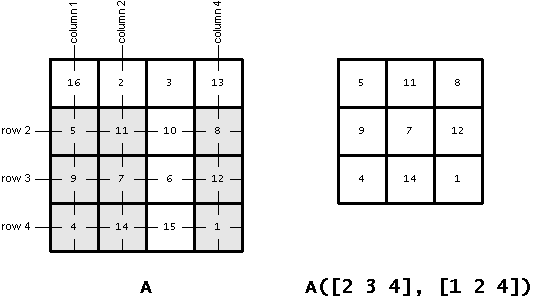

# Linear indexing

When you index into A with only 1 subscript, MATLAB flattens the matrix into one long column

A(:)

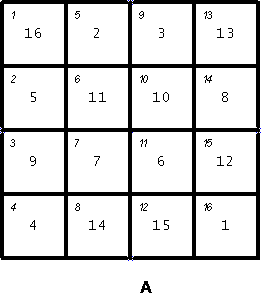

A(14)    % WRITEME INCOMMENTS: What does this give you?

Consider the aforementioned problem again: To index (2,1), (3,2), (4,4), you'll need to do 

A([2 7 16])

But lucky enough, MATLAB has a function that would calculate the linear index for you!

ind = sub2ind(size(A),[2 3 4],[1 2 4])

# Logical Operators

Before we discuss logical indexing,we need to address the idea of logic in MATLAB. We hope you are familiar with *and*, *or*, and *not* from DLD. In MATLAB, you can apply such concepts for logical arrays. Logical arrays are arrays of 0(false) and 1(true). Note that an array of 0 and 1 might not necessary be a logical array, but you can convert a normal array to a logical array.

B = eye(4);
C = logical([1 1 1 1; 1 0 0 0; 1 0 0 0; 1 0 0 0]);
islogical(B)
islogical(C)
logical(B); % makes B a logical matrix

B & C;      % and(B,C) is equivalent to B&C
B | C;      % or(B,C) is equivalent to B|C
~(B & C);   % not(and(B,C)) is equivalent to ~(B&C)
not(B & C); % you can use both representations intermittenly 

true(2,5)   % creates a 2-by-5 matrix with all elements = 1

Note: not(2) and not(-2) both give you one, only not(0) gives you zero. 

# Logical Indexing *** VERY IMPORTANT ***

Another indexing variation, *logical indexing*, has proven to be both useful and expressive. In logical indexing, you use a single, logical array for the matrix subscript. MATLAB extracts the matrix elements corresponding to the nonzero values of the logical array. The output is always in the form of a column vector. For example, `A(A > 12)` extracts all the elements of `A` that are greater than 12. 

A(A > 12)

The expression A > 12 creates a logical array, where each element would show 1 if the expression evaluates to true, and false vice versa

A > 12

And if you want to find the index where A > 12, you can write

find(A > 12)

# Practical example of vector operations : Numerical Estimation of integrals and derivatives

## Approximate Derivatives

Here we will look at some approximate numerical methods

x = linspace(-2,2,100);
y = x.^2;
plot(x,y)
title('x^2')

Now, we can approximate the derivative


$$\frac{dy}{dx}=\lim_{\Delta x\to 0} \frac{y\left(x+\Delta x\right)-y\left(x\right)}{\Delta x}$$


as


$$\hat{\frac{\text{dy}}{\text{dx}}} =\frac{y\left(x+\Delta x\right)-y\left(x\right)}{\Delta x}=\frac{\Delta y}{\Delta x}$$


where$\Delta x$ is small.

An easy way to do this in MATLAB is the *diff* command which returns the difference between every pair of consecutive numbers in a vector (or each column of an array).

dydx = diff(y)./diff(x);

 *diff *returns one less element than the original vector, this simple strategry returns an error.  Fix this by plotting against a new x, *xhat.  *Note that there are many valid ways to do this. You will need *xhat *later so make sure you get it!

xhat = x(1:end-1)
plot(xhat,dydx)

## Approximate Integrals

Now suppose we want to approximate the cumulative integral of a function, i.e.


$$Y\left(u\right)=\int_c^u y\left(x\right)dx=\lim_{\Delta x\to 0} \text{  }\sum_{c+n\Delta x\text{ }\in \left\lbrack c,u\right\rbrack } y\left(c+n\Delta x\right)\Delta x\text{ }$$


Again, we can approximate this by simply dropping the limit


$$\hat{Y} =\sum_{c+n\Delta x\text{ }\in \left\lbrack c,u\right\rbrack } y\left(c+n\Delta x\right)\Delta x\text{ }$$


The *cumsum* function in MATLAB returns the running sum of a vector, i.e.


$${cumsum\left(v\right)}_{1,n} =\sum v\left(1:n\right)$$


Y = cumsum(y).*(x(2)-x(1))
plot(x,Y)